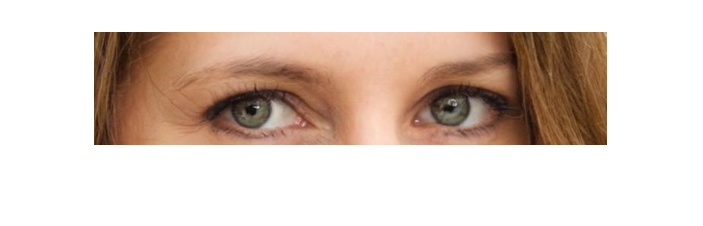

imshow(soloOjos);

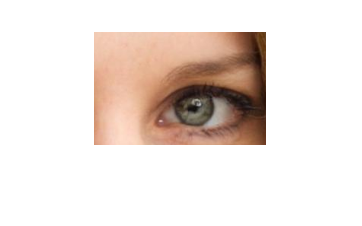

mitad = imcrop(soloOjos, [width(soloOjos)/2, 0, round(width(soloOjos)/3), height(soloOjos)]);
imshow(mitad)

I = rgb2gray(mitad);

corners = detectHarrisFeatures(I);

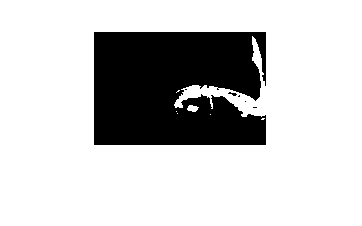

ocurrenciasnegro = I(:, :) < 50;
%imshow(ocurrenciasnegro);
suelo = sum(ocurrenciasnegro);
[maximox, coordenadax] = max(suelo);
columna = sum(transpose(ocurrenciasnegro));
[maximoy, coordenaday] = max(columna);
imshow(ocurrenciasnegro)

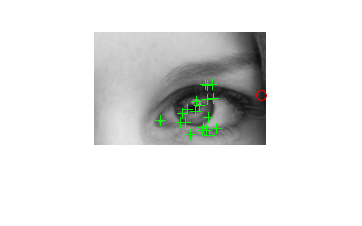

imshow(I); hold on;
plot(corners.selectStrongest(50));
plot(coordenadax, coordenaday, 'o', 'Color', 'red');
hold off;

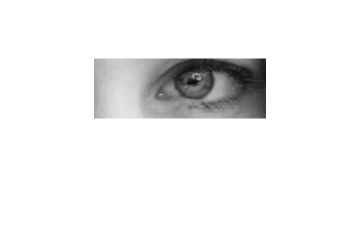

imagenAcotada = I((coordenaday-10):height(I), :, :);
imshow(imagenAcotada)

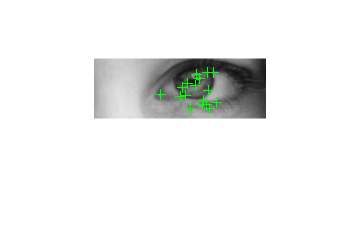

corners = detectHarrisFeatures(imagenAcotada);
imshow(imagenAcotada); hold on;
plot(corners.selectStrongest(50));
hold off;